## Espace de solutions suivant une trajectoire et qui respecte les butées articulaires et qui évite les singularitées du robot

### **Definition des variables**

% Définir les symboles pour les angles d'articulation
syms theta1 theta2 theta3 theta4;

% Définir les longueurs des bras
a1 = 2; % Longueur du premier bras
a2 = 3; % Longueur du deuxième bras
a3 = 2; % Longueur du troisième bras
a4 = 2; % Longueur du quatrieme bras
a5 = 2; % Longueur du cinquieme bras

### Definition et affichage de la trajectoire

% Définir la trajectoire souhaitée (par exemple, un cercle)
num_points = 10;
radius = 9;
theta_traj = linspace(0, pi/3, num_points);
x_traj = radius * cos(theta_traj);
y_traj = radius * sin(theta_traj);
% Combiner les coordonnées x et y en une seule matrice de points de trajectoire
trajectory_points = [x_traj', y_traj'];
% Afficher les points de la trajectoire sous forme de tableau
disp('Points de la trajectoire :');

Points de la trajectoire :


fprintf('-------------------------------------------------\n');

-------------------------------------------------


fprintf('| Point  |      X     |      Y     |\n');

| Point  |      X     |      Y     |


fprintf('-------------------------------------------------\n');

-------------------------------------------------


for i = 1:num_points
    fprintf('|   %2d   |   %7.2f   |   %7.2f   |\n', i, x_traj(i), y_traj(i));
end

|    1   |      9.00   |      0.00   |
|    2   |      8.94   |      1.04   |
|    3   |      8.76   |      2.08   |
|    4   |      8.46   |      3.08   |
|    5   |      8.04   |      4.04   |
|    6   |      7.52   |      4.95   |
|    7   |      6.89   |      5.79   |
|    8   |      6.18   |      6.55   |
|    9   |      5.37   |      7.22   |
|   10   |      4.50   |      7.79   |


fprintf('-------------------------------------------------\n')

-------------------------------------------------


**Recuperation des solutions calculées dans le fichier ***Config_Robot_Redondant_SuiviTraj*

On définit tout d'abord les variables du code puis l'espace de solutions sans conditions de filtrage pour atteindre le point cible est recupéré pour ensuite afficher les differentes configuration articulaires possibles en radian

% Charger les solutions depuis le fichier
load('finalresCIRand.mat');

fprintf('Résultats des diffrents sets de positions que peut avoir le robot pour suivre la trajectoire selon la position initiale en RADIAN:\n');

Résultats des diffrents sets de positions que peut avoir le robot pour suivre la trajectoire selon la position initiale en RADIAN:


fprintf(' CI Point  PointTraj    Theta1    Theta2    Theta3    Theta4    Theta5    Xcalc     Ycalc\n');

 CI Point  PointTraj    Theta1    Theta2    Theta3    Theta4    Theta5    Xcalc     Ycalc


fprintf('------------------------------------------------\n');

------------------------------------------------


disp(final_results_all_with_CIRand);

    1.0000    1.0000    0.0873    5.6621    1.6584    5.4888    5.3702    9.0000    0.0000
    1.0000    2.0000    0.0300    5.7947    1.7297    5.5229    5.4798    8.9391    1.0448
    1.0000    3.0000    6.0513    6.2092    1.1688    5.4340    1.2261    8.7574    2.0755
    1.0000    4.0000    6.1969    6.1653    1.1771    5.4355    1.2356    8.4572    3.0782
    1.0000    5.0000    0.0651    6.1152    1.1820    5.4368    1.2516    8.0427    4.0392
    1.0000    6.0000    0.2173    6.0662    1.1835    5.4373    1.2707    7.5194    4.9456
    1.0000    7.0000    0.3665    6.0232    1.1813    5.4368    1.2910    6.8944    5.7851
    1.0000    8.0000    0.5129    5.9875    1.1743    5.4343    1.3151    6.1762    6.5464
    1.0000    9.0000    0.8645    5.8086    0.9651    5.3611    1.6282    5.3744    7.2191
    1.0000   10.0000    0.5718    0.2043    1.0169    4.8979    1.5304    4.5000    7.7942
    2.0000    1.0000    0.3989    4.8698    1.6319    5.7478    0.1448    9.0000    0.0000

fprintf('------------------------------------------------\n');

------------------------------------------------



final_results_all_with_CIRand(:, 3:7) = rad2deg(final_results_all_with_CIRand(:, 3:7));
final_results_all_with_CIRand(:, 3:7) = mod(final_results_all_with_CIRand(:, 3:7)+ 180, 360) - 180;

fprintf('Résultats des diffrents sets de positions que peut avoir le robot pour suivre la trajectoire selon la position initiale en DEGRES:\n');

Résultats des diffrents sets de positions que peut avoir le robot pour suivre la trajectoire selon la position initiale en DEGRES:


fprintf(' CI Point  PointTraj    Theta1    Theta2    Theta3    Theta4    Theta5    Xcalc     Ycalc\n');

 CI Point  PointTraj    Theta1    Theta2    Theta3    Theta4    Theta5    Xcalc     Ycalc


fprintf('------------------------------------------------\n');

------------------------------------------------


disp(final_results_all_with_CIRand);

    1.0000    1.0000    5.0034  -35.5865   95.0171  -45.5156  -52.3088    9.0000    0.0000
    1.0000    2.0000    1.7214  -27.9895   99.1041  -43.5591  -46.0309    8.9391    1.0448
    1.0000    3.0000  -13.2856   -4.2378   66.9650  -48.6540   70.2502    8.7574    2.0755
    1.0000    4.0000   -4.9451   -6.7541   67.4413  -48.5672   70.7958    8.4572    3.0782
    1.0000    5.0000    3.7323   -9.6250   67.7255  -48.4969   71.7126    8.0427    4.0392
    1.0000    6.0000   12.4505  -12.4350   67.8076  -48.4645   72.8031    7.5194    4.9456
    1.0000    7.0000   21.0016  -14.8935   67.6841  -48.4930   73.9696    6.8944    5.7851
    1.0000    8.0000   29.3848  -16.9438   67.2798  -48.6387   75.3520    6.1762    6.5464
    1.0000    9.0000   49.5346  -27.1930   55.2970  -52.8295   93.2878    5.3744    7.2191
    1.0000   10.0000   32.7629   11.7040   58.2632  -79.3717   87.6856    4.5000    7.7942
    2.0000    1.0000   22.8538  -80.9827   93.4991  -30.6749    8.2936    9.0000    0.0000

fprintf('------------------------------------------------\n');

------------------------------------------------


### Definir position de l'obstacle

x_min=4;
x_max=8;
y_min=-2;
y_max=-1;

% Définir les coordonnées des coins du rectangle représentant l'objet fixe
obstacle_coords = [x_min, y_min; x_min, y_max; x_max, y_max; x_max, y_min];

## Filtrage des solutions

### CI pour laquelle toutes les solutions respectent la continuite, la singularite et les butees articulaires, et les collisions

Cette partie tri notre espace de solutions, en fonction des butées de chaque articulations et des positions de singularitées. De cette manière, nous pouvons observer dans la table ci-dessous les configurations (en gras), qui respectent bien ces deux conditions.

Ainsi, on a dans la derniere table le resultat final de notre espace de travail qui repond aux differentes conditions de filtrage des solutions 

disp('Butées de chaque theta:')

Butées de chaque theta:


% Chargement de la matrice butee à partir du fichier .mat
load('butee.mat'); % Charge la matrice butee à partir du fichier butee.mat
disp(butee);

   -90    90
   -95    95
   -90    90
   -90    90
   -90    90




% % Filtrage des solutions pour les butées articulaires
% trisolution = solutions_filtrees_continues(:, 3:7) >= butee(:, 1)' & solutions_filtrees_continues(:, 3:7) <= butee(:, 2)';
% 
% % Vérification des singularités pour les solutions filtrées
% singularite = check_singularities(deg2rad(solutions_filtrees_continues(:, 3:7)), a1, a2, a3, a4, a5);

% Initialiser le seuil de différence
seuil = 30; % Vous pouvez ajuster cela selon vos besoins

% Initialiser la CI respectée à une valeur qui n'existe pas dans vos données
ci_continuite = [];

% Initialiser une matrice pour stocker les CI où tous les points de la trajectoire respectent les critères
ci_all_points_valid = [];

% Initialiser une matrice pour stocker les solutions filtrées
solutions_filtrees_CI_completecr = [];

% Pour chaque configuration initiale
for ci = 1:max(final_results_all_with_CIRand(:, 1))
    % Extraire les indices correspondant à cette configuration initiale
    indices = final_results_all_with_CIRand(:, 1) == ci;
    % Extraire les données pour cette configuration initiale
    data_for_ci = final_results_all_with_CIRand(indices, :);
    % Initialiser le drapeau pour suivre si la différence est respectée pour tous les points
    diff_respected = true;
    % Pour chaque point de la trajectoire pour cette configuration initiale
    for i = 1:size(data_for_ci, 1)-1
        % Calculer la différence entre le point actuel et le point suivant
        theta1_diff_deg = abs(data_for_ci(i, 3) - data_for_ci(i+1, 3));
        theta2_diff_deg = abs(data_for_ci(i, 4) - data_for_ci(i+1, 4));
        theta3_diff_deg = abs(data_for_ci(i, 5) - data_for_ci(i+1, 5));
        theta4_diff_deg = abs(data_for_ci(i, 6) - data_for_ci(i+1, 6));
        theta5_diff_deg = abs(data_for_ci(i, 7) - data_for_ci(i+1, 7));
        % Vérifier si la différence absolue est en dessous du seuil
        if theta1_diff_deg >= seuil || theta2_diff_deg >= seuil || theta3_diff_deg >= seuil || theta4_diff_deg >= seuil || theta5_diff_deg >= seuil
            % Mettre à jour le drapeau si la différence n'est pas respectée pour ce point
            diff_respected = false;
            break; % Sortir de la boucle dès qu'une différence n'est pas respectée
        end 
    end    
    % Si la différence est respectée pour tous les points, ajouter la CI à la liste des CI respectées
    if diff_respected
        ci_continuite = [ci_continuite, ci];
        collision_detected = false;
        % Vérifier les collisions pour chaque point de la trajectoire
        for i = 1:size(data_for_ci, 1)
            % Calculer les positions des articulations du robot avec les valeurs des angles d'articulation calculées
            theta1 = mod(deg2rad(data_for_ci(i, 3)), 2*pi);
            theta2 = mod(deg2rad(data_for_ci(i, 4)), 2*pi);
            theta3 = mod(deg2rad(data_for_ci(i, 5)), 2*pi);
            theta4 = mod(deg2rad(data_for_ci(i, 6)), 2*pi);
            theta5 = mod(deg2rad(data_for_ci(i, 7)), 2*pi);
    
            % Calculer les positions des articulations du robot
            % Calculer les positions des articulations du robot
            O = [0, 0]; % Position de l'origine
            A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
            B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
            C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
            D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
            E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)
            % Matrice des segments du robot
            segments_robot = {[O; A], [A; B], [B; C], [C; D], [D; E]};
            % Vérifier les collisions pour chaque segment du robot
            for j = 1:numel(segments_robot)-1
                segment = [segments_robot{j}; segments_robot{j+1}];
                collision_detected = checkCollisionSegmentObstacle(segment, obstacle_coords);
                % Si une collision est détectée, sortir des boucles
                if collision_detected
                    break;
                end
            end
    
            % Si une collision est détectée, sortir des boucles
            if collision_detected
                break;
            end
        end
    
        % Si aucune collision n'a été détectée pour l'ensemble de la trajectoire, ajouter la solution
        if ~collision_detected
            % Si toutes les solutions pour cette CI sont valides, ajouter la CI à la liste des CI où tous les points de la trajectoire respectent les critères
            if all(check_singularities(deg2rad(data_for_ci(:, 3:7)), a1, a2, a3, a4, a5) == 0) && all(all(data_for_ci(:, 3:7) >= butee(:, 1)' & data_for_ci(:, 3:7) <= butee(:, 2)'))
                % Ajouter la solution à la matrice des solutions filtrées complètes
                ci_all_points_valid = [ci_all_points_valid, ci];
                % Ajouter la solution à la matrice des solutions filtrées complètes
                solutions_filtrees_CI_completecr = [solutions_filtrees_CI_completecr; data_for_ci];
            end
        end
    end
end

collision
collision
collision


        

% Afficher la liste des CI où tous les points de la trajectoire respectent les critères
if isempty(ci_all_points_valid)
    fprintf('Aucune configuration initiale ne respecte tous les critères pour tous les points de la trajectoire.\n');
else 
    fprintf('Liste des CI où tous les points de la trajectoire respectent les critères : \n');
    disp(ci_all_points_valid);
end

Liste des CI où tous les points de la trajectoire respectent les critères : 


    27




% Afficher les résultats filtrés
fprintf('Résultats filtrés (en degrés ajustés) : \n');

Résultats filtrés (en degrés ajustés) : 


fprintf('| %-7s | %-9s | %-9s | %-9s | %-9s | %-9s | %-9s | %-11s | %-11s |\n', 'CI', 'Point', 'Theta1', 'Theta2', 'Theta3', 'Theta4', 'Theta5', 'X_calculé', 'Y_calculé');

| CI      | Point     | Theta1    | Theta2    | Theta3    | Theta4    | Theta5    | X_calculé   | Y_calculé   |


fprintf('__________________________________________________________________________________________________________________\n');

__________________________________________________________________________________________________________________


disp(solutions_filtrees_CI_completecr);

   27.0000    1.0000  -24.0508   37.9850   50.5302  -73.2965  -35.7911    9.0000   -0.0000
   27.0000    2.0000  -23.0774   43.0343   52.2031  -71.9708  -33.7481    8.9391    1.0448
   27.0000    3.0000  -20.4409   46.9617   51.9869  -69.9510  -32.8565    8.7574    2.0755
   27.0000    4.0000  -15.9586   49.8368   50.1167  -67.9545  -33.0740    8.4572    3.0782
   27.0000    5.0000   -9.4668   51.6213   46.6424  -66.2311  -34.4624    8.0427    4.0392
   27.0000    6.0000   -1.3187   52.4358   41.7730  -64.4789  -36.8277    7.5194    4.9456
   27.0000    7.0000    7.9746   52.4584   35.7368  -62.2223  -39.8880    6.8944    5.7851
   27.0000    8.0000   18.0182   51.8253   28.7523  -59.1353  -43.3929    6.1762    6.5464
   27.0000    9.0000   28.8461   50.4847   20.6017  -54.9121  -47.2754    5.3744    7.2191
   27.0000   10.0000   42.0236   47.7281    8.3265  -47.9886  -51.7763    4.5000    7.7942



### Visualisation de chaque robot dans un graphique séparé pour chaque configuration initiale

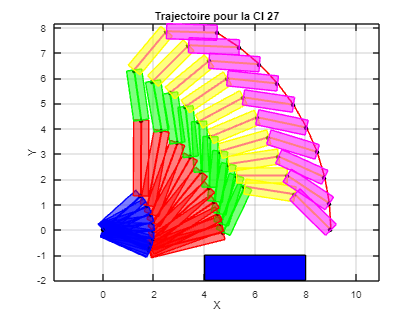

% Définir les couleurs pour chaque type de segment
color_segment_OA = 'b'; % Segment OA
color_segment_AB = 'r'; % Segment AB
color_segment_BC = 'g'; % Segment BC
color_segment_CD = 'm'; % Segment CD
color_segment_DE = 'y'; % Segment DE

% Pour chaque configuration initiale
% Pour chaque CI où tous les points de la trajectoire respectent les critères
for ci = ci_all_points_valid
    % Extraire les indices correspondant à cette configuration initiale
    indices = solutions_filtrees_CI_completecr(:, 1) == ci;
    
    % Extraire les données pour cette configuration initiale
    data_for_ci = solutions_filtrees_CI_completecr(indices, :);

    % Afficher la trajectoire
    figure;
    plot(x_traj, y_traj, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Trajectoire à suivre' );
    axis equal; % Pour que l'échelle des axes soit égale
    xlabel('X');
    ylabel('Y');
    title(['Trajectoire pour la CI ', num2str(ci_all_points_valid(1))]);
    grid on;
    hold on;
    rectangle('Position', [x_min, y_min, x_max - x_min, y_max - y_min], ...
          'EdgeColor', 'k', 'FaceColor', 'b');
    % Pour chaque point de la trajectoire pour cette configuration initiale
    for i = 1:size(data_for_ci, 1)
        
        % Convertir les angles de degrés en radians et les restreindre dans l'intervalle [0, 2*pi]
        theta1 = mod(deg2rad(data_for_ci(i, 3)), 2*pi);
        theta2 = mod(deg2rad(data_for_ci(i, 4)), 2*pi);
        theta3 = mod(deg2rad(data_for_ci(i, 5)), 2*pi);
        theta4 = mod(deg2rad(data_for_ci(i, 6)), 2*pi);
        theta5 = mod(deg2rad(data_for_ci(i, 7)), 2*pi);

        % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
        O = [0, 0]; % Position de l'origine
        A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
        B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
        C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
        D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
        E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)
        % Matrice des segments du robot
        segments_robot = {[O; A], [A; B], [B; C], [C; D], [D; E]};

        % Tracer le robot pour cette configuration initiale
        plot([O(1), A(1)], [O(2), A(2)], 'LineWidth', 2, 'Color', color_segment_OA); % Segment OA
        plot([A(1), B(1)], [A(2), B(2)], 'LineWidth', 2, 'Color', color_segment_AB); % Segment AB
        plot([B(1), C(1)], [B(2), C(2)], 'LineWidth', 2, 'Color', color_segment_BC); % Segment BC
        plot([C(1), D(1)], [C(2), D(2)], 'LineWidth', 2, 'Color', color_segment_CD); % Segment CD
        plot([D(1), E(1)], [D(2), E(2)], 'LineWidth', 2, 'Color', color_segment_DE); % Segment DE
        scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'HandleVisibility', 'off'); % Marques pour les articulations
        
        % Ajouter des rectangles autour des segments
        rectWidth = 0.3; % Ajustez cette valeur selon vos besoins
        drawSegmentRectangle(O, A, rectWidth, 'b');
        drawSegmentRectangle(A, B, rectWidth, 'r');
        drawSegmentRectangle(B, C, rectWidth, 'g');
        drawSegmentRectangle(C, D, rectWidth, 'y');
        drawSegmentRectangle(D, E, rectWidth, 'm');
        % % Vérifier la collision pour chaque segment du robot
        % 
        % for j = 1:numel(segments_robot)-1
        %     segment = [segments_robot{j}; segments_robot{j+1}];
        %     collision_detected = checkCollisionSegmentObstacle(segment, obstacle_coords);
        %     if collision_detected
        %         disp('Collision détectée !');
        %         break; % Sortir de la boucle dès qu'une collision est détectée
        %     end
        % end
        % 
        % if collision_detected
        %     break; % Sortir de la boucle principale dès qu'une collision est détectée
        % end
        % Mettre en pause pour une durée appropriée
        pause(0.1); % Changer cette valeur pour ajuster la vitesse de l'animation
    end
    hold off;
end

function collision_detected = checkCollisionSegmentObstacle(segment, obstacle_coords)
    % Extraire les coordonnées des points du segment
    x1 = segment(1, 1);
    y1 = segment(1, 2);
    x2 = segment(2, 1);
    y2 = segment(2, 2);

    % Pour chaque côté de l'obstacle
    for i = 1:size(obstacle_coords, 1)
        % Extraire les coordonnées des points du côté de l'obstacle
        x3 = obstacle_coords(i, 1);
        y3 = obstacle_coords(i, 2);
        if i < size(obstacle_coords, 1)
            x4 = obstacle_coords(i+1, 1);
            y4 = obstacle_coords(i+1, 2);
        else
            x4 = obstacle_coords(1, 1);
            y4 = obstacle_coords(1, 2);
        end

        % Vérifier s'il y a intersection entre le segment et le côté de l'obstacle
        collision_detected = doIntersect(x1, y1, x2, y2, x3, y3, x4, y4);
        if collision_detected
            disp('collision');
            return; % Si une collision est détectée, sortir de la fonction
        end
    end

    % Aucune collision détectée
    collision_detected = false;
end

% Vérifier s'il y a intersection entre deux segments de ligne
function intersect = doIntersect(x1, y1, x2, y2, x3, y3, x4, y4)
    % Calculer les orientations
    orientation1 = (y2 - y1) * (x3 - x2) - (x2 - x1) * (y3 - y2);
    orientation2 = (y2 - y1) * (x4 - x2) - (x2 - x1) * (y4 - y2);
    orientation3 = (y4 - y3) * (x1 - x4) - (x4 - x3) * (y1 - y4);
    orientation4 = (y4 - y3) * (x2 - x4) - (x4 - x3) * (y2 - y4);

    % Vérifier s'il y a intersection
    intersect = (orientation1 * orientation2 < 0) & (orientation3 * orientation4 < 0);
end

function in_workspace = point_in_workspace(x, y, points_atteign, K)
    % Vérifie si le point (x, y) est dans l'espace de travail du robot
    in_workspace = inpolygon(x, y, points_atteign(K, 1), points_atteign(K, 2));
end

function drawSegmentRectangle(startPoint, endPoint, rectWidth, color)
    % Calcule la longueur et l'angle du segment
    segmentLength = norm(endPoint - startPoint);
    segmentAngle = atan2(endPoint(2) - startPoint(2), endPoint(1) - startPoint(1));
    
    % Calcule les coordonnées des coins du rectangle
    dx = rectWidth * cos(segmentAngle + pi/2);
    dy = rectWidth * sin(segmentAngle + pi/2);
    rectPoints = [startPoint(1) - dx, startPoint(2) - dy;
                  startPoint(1) + dx, startPoint(2) + dy;
                  endPoint(1) + dx, endPoint(2) + dy;
                  endPoint(1) - dx, endPoint(2) - dy;
                  startPoint(1) - dx, startPoint(2) - dy];
    
    % Trace le rectangle
    fill(rectPoints(:, 1), rectPoints(:, 2), color, 'EdgeColor', color, 'FaceAlpha', 0.5, 'HandleVisibility', 'off');
end